% tarsk-3                    elleptical particles  shaped centroid

ds1=imageDatastore("C:\Users\Adarsh Kumar\Desktop\static\srip_prct\elliptical","IncludeSubfolders",true,"LabelSource","foldernames")

ds1 =   ImageDatastore with properties:

                       Files: {
                              'C:\Users\Adarsh Kumar\Desktop\static\srip_prct\elliptical\Img_7_1.tif';
                              ' ...\Users\Adarsh Kumar\Desktop\static\srip_prct\elliptical\Img_7_2939.tif';
                              ' ...\Users\Adarsh Kumar\Desktop\static\srip_prct\elliptical\Img_7_5989.tif'
                              }
                     Folders: {
                              'C:\Users\Adarsh Kumar\Desktop\static\srip_prct\elliptical'
                              }
                      Labels: [elliptical; elliptical; elliptical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


img1=readimage(ds1,2)

img1 = 580×780 uint8 matrix
    89    71    71    84   104   135   166   190   204   219   223   233   231   243   243   243   243   223   184   134    97    78    79    92   126   162   199   227   239   243   243   243   237   226   214   179   143   111    82    80    89   120   164   204   237   243   220   173   119    79
    92    88   101   125   157   187   205   220   228   227   225   231   232   243   243   236   224   191   149   107    86    80    92   117   158   191   217   233   234   242   235   230   221   210   180   147   112    85    74    79   103   136   187   221   235   238   215   171   120    80
    94   107   136   167   199   221   231   229   234   223   220   224   230   234   229   220   197   160   123    93    85    91   112   139   180   214   225   228   234   240   234   223   202   183   155   123    87    69    71    88   121   164   204   229   241   230   205   167   123    90
    98   127   165   204   234   243   241   237   227   221   220   

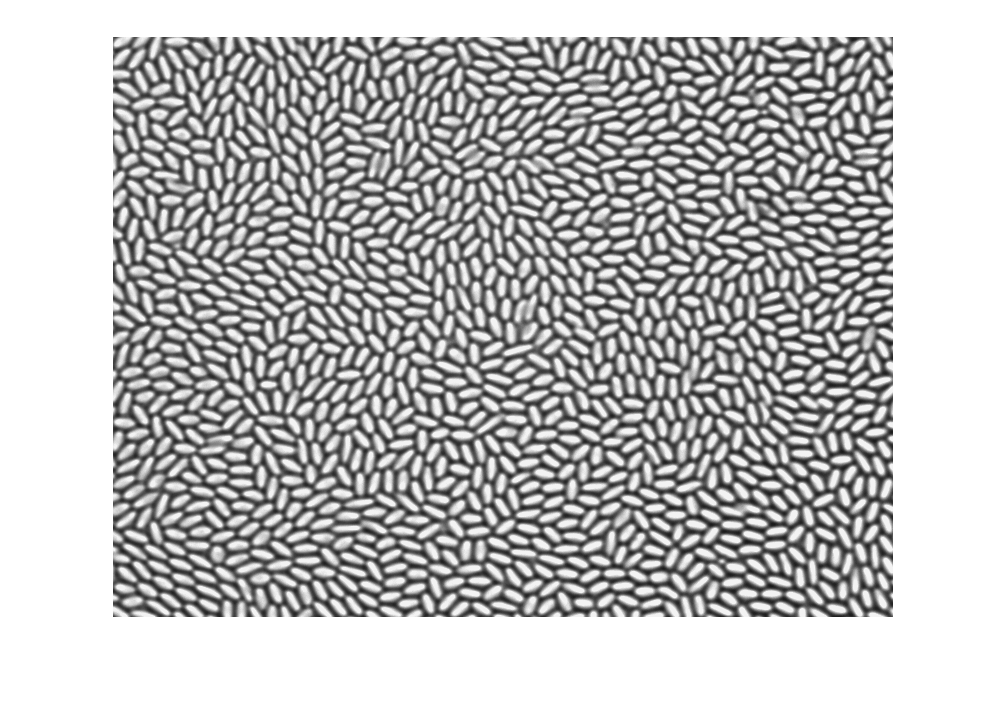

imshow(img1)

img2=img1>150

img2 = 580×780 logical array
   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   0   0
   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   1   1   1   1   1   1   0   0
   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   1   0   0
   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   1   1   1   1   1   1   1   0   0
   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   1   

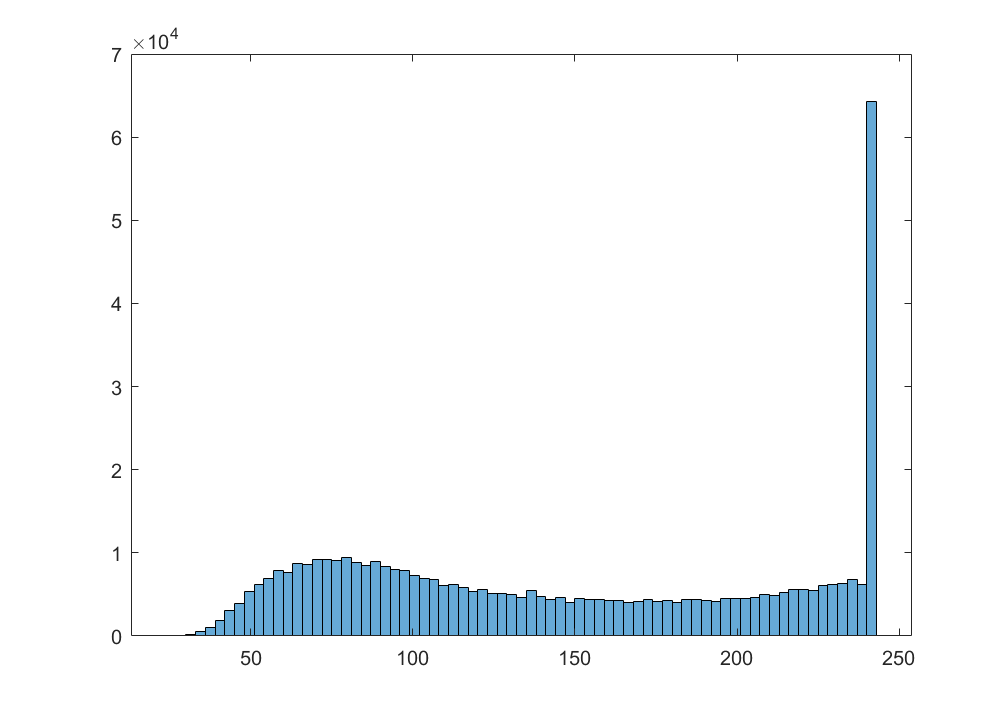

histogram(img1)

rp=regionprops(img2,"all")

rp = 1465×1 struct array with fields:
    Area
    Centroid
    BoundingBox
    SubarrayIdx
    MajorAxisLength
    MinorAxisLength
    Eccentricity
    Orientation
    ConvexHull
    ConvexImage
    ConvexArea
    Circularity
    Image
    FilledImage
    FilledArea
    EulerNumber
    Extrema
    EquivDiameter
    Solidity
    Extent
    PixelIdxList
    PixelList
    Perimeter
    PerimeterOld
    MaxFeretDiameter
    MaxFeretAngle
    MaxFeretCoordinates
    MinFeretDiameter
    MinFeretAngle
    MinFeretCoordinates


t=linspace(0,2*pi,360)

t =          0    0.0175    0.0350    0.0525    0.0700    0.0875    0.1050    0.1225    0.1400    0.1575    0.1750    0.1925    0.2100    0.2275    0.2450    0.2625    0.2800    0.2975    0.3150    0.3325    0.3500    0.3675    0.3850    0.4025    0.4200    0.4375    0.4550    0.4726    0.4901    0.5076    0.5251    0.5426    0.5601    0.5776    0.5951    0.6126    0.6301    0.6476    0.6651    0.6826    0.7001    0.7176    0.7351    0.7526    0.7701    0.7876    0.8051    0.8226    0.8401    0.8576


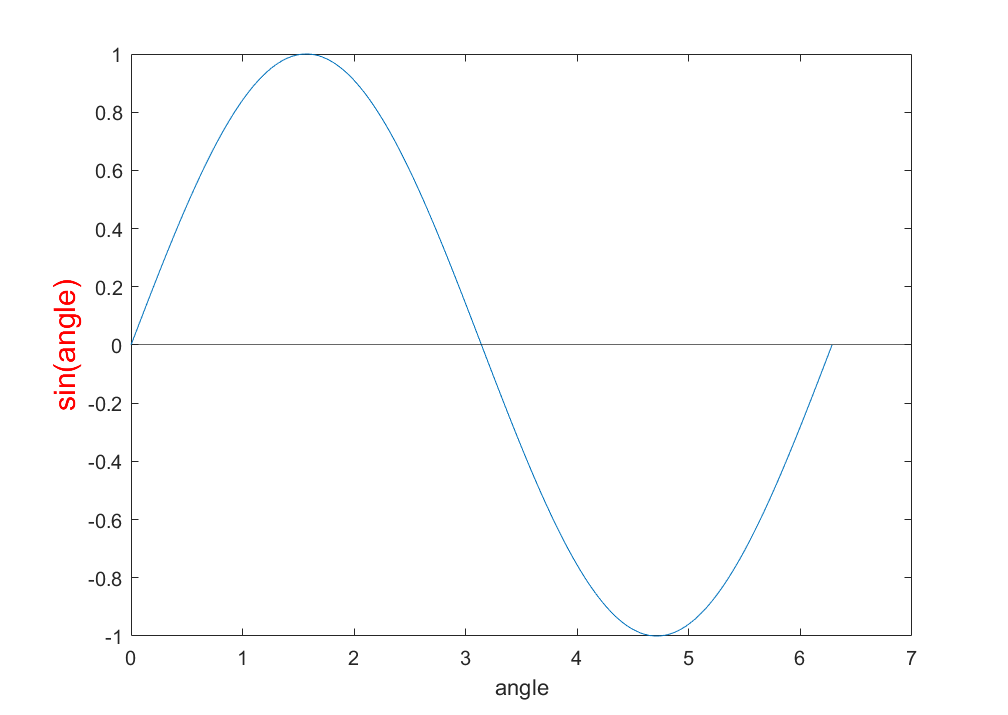

plot(t,sin(t))
xlabel("angle")
ylabel("sin(angle)","FontSize",15,"Color","r")
hold on
yline(0)
hold off

rp

rp = 1465×1 struct array with fields:
    Area
    Centroid
    BoundingBox
    SubarrayIdx
    MajorAxisLength
    MinorAxisLength
    Eccentricity
    Orientation
    ConvexHull
    ConvexImage
    ConvexArea
    Circularity
    Image
    FilledImage
    FilledArea
    EulerNumber
    Extrema
    EquivDiameter
    Solidity
    Extent
    PixelIdxList
    PixelList
    Perimeter
    PerimeterOld
    MaxFeretDiameter
    MaxFeretAngle
    MaxFeretCoordinates
    MinFeretDiameter
    MinFeretAngle
    MinFeretCoordinates


length(rp)

ans = 1465

rp(6)                % element indexing

ans = struct with fields:
                   Area: 74
               Centroid: [4.2838 89.2297]
            BoundingBox: [0.5000 81.5000 9 13]
            SubarrayIdx: {[82 83 84 85 86 87 88 89 90 91 92 93 94]  [1 2 3 4 5 6 7 8 9]}
        MajorAxisLength: 13.3988
        MinorAxisLength: 7.6991
           Eccentricity: 0.8184
            Orientation: -57.2170
             ConvexHull: [40×2 double]
            ConvexImage: [13×9 logical]
             ConvexArea: 76
            Circularity: 0.8920
                  Image: [13×9 logical]
            FilledImage: [13×9 logical]
             FilledArea: 74
            EulerNumber: 1
                Extrema: [8×2 double]
          EquivDiameter: 9.7067
               Solidity: 0.9737
                 Extent: 0.6325
           PixelIdxList: [74×1 double]
              PixelList: [74×2 double]
              Perimeter: 32.2870
           PerimeterOld: 33.5563
       MaxFeretDiameter: 15
          MaxFeretAngle: -126.8699
    MaxFeretCoordinate

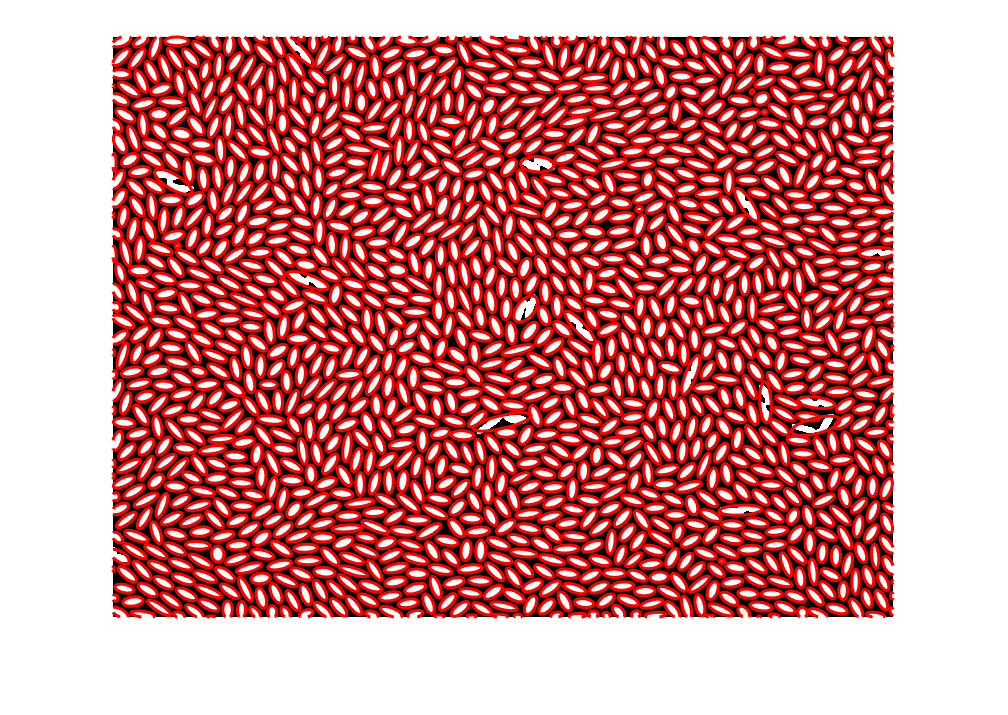


imshow(img2)
hold on
for i=1:length(rp)
    cx=rp(i).Centroid(1);
    cy=rp(i).Centroid(2);
    a=rp(i).MajorAxisLength/2;                    % 
    b=rp(i).MinorAxisLength/2;
    o=rp(i).Orientation;
    orient=deg2rad(-o);
    x=cx+a*cos(t)*cos(orient)-b*sin(t)*sin(orient);
    y=cy+a*cos(t)*sin(orient)+b*sin(t)*cos(orient);
    plot(x,y,"r","LineWidth",1.54)
end
hold off

dd=struct2table(rp) % converting structure data to table for smooth in dexing

dd = 1465×30 table
    Area        Centroid                 BoundingBox                       SubarrayIdx              MajorAxisLength    MinorAxisLength    Eccentricity    Orientation     ConvexHull        ConvexImage      ConvexArea    Circularity         Image           FilledImage      FilledArea    EulerNumber      Extrema       EquivDiameter    Solidity    Extent      PixelIdxList       PixelList       Perimeter    PerimeterOld    MaxFeretDiameter    MaxFeretAngle    MaxFeretCoordinates    MinFeretDiameter    

pp=dd([1:end], [2])  % accesing only centroid column

pp = 1465×1 table
        Centroid    
    ________________

    9.0938    5.0703
    9.0067    20.633
     8.392    37.616
         1      49.5
     7.576        63
    4.2838     89.23
     7.443    107.03
    1.8913    126.09
       5.6    142.92
    6.8742    161.73
         1     178.5
    4.4179    197.37
     1.925    218.03
    5.0841    255.46
     3.717    270.45
    10.843    285.04


pp.Centroid([1,1])     % accessing first element in pp

ans =     9.0938    9.0938


x=pp.Centroid([1:end],[1])

x =     9.0938
    9.0067
    8.3920
    1.0000
    7.5760
    4.2838
    7.4430
    1.8913
    5.6000
    6.8742


y=pp.Centroid([1:end],[2])

y =     5.0703
   20.6333
   37.6160
   49.5000
   63.0000
   89.2297
  107.0316
  126.0870
  142.9231
  161.7285


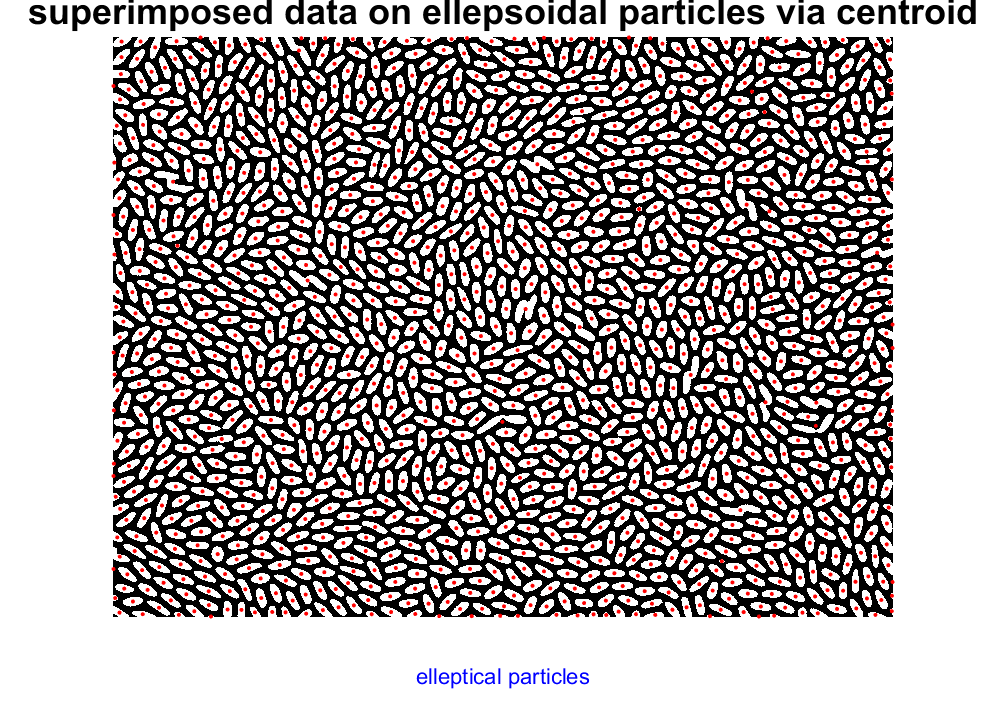

imshow(img2)
hold on
plot(x,y,".r")
title("superimposed data on ellepsoidal particles via centroid","FontSize",18)
xlabel("elleptical particles","Color","b")
hold off

% part2 --------------trial

cnc=bwconncomp(img2)  

cnc = struct with fields:
    Connectivity: 8
       ImageSize: [580 780]
      NumObjects: 1465
    PixelIdxList: {1×1465 cell}


% bw-binaery worksapce,
% Connected component labeling works by scanning an image, 
% pixel-by-pixel (from top to bottom and left to right) in order to identify connected pixel regions,
% i.e. regions of adjacent pixels which share the same set of intensity values V

img1

img1 = 580×780 uint8 matrix
    89    71    71    84   104   135   166   190   204   219   223   233   231   243   243   243   243   223   184   134    97    78    79    92   126   162   199   227   239   243   243   243   237   226   214   179   143   111    82    80    89   120   164   204   237   243   220   173   119    79
    92    88   101   125   157   187   205   220   228   227   225   231   232   243   243   236   224   191   149   107    86    80    92   117   158   191   217   233   234   242   235   230   221   210   180   147   112    85    74    79   103   136   187   221   235   238   215   171   120    80
    94   107   136   167   199   221   231   229   234   223   220   224   230   234   229   220   197   160   123    93    85    91   112   139   180   214   225   228   234   240   234   223   202   183   155   123    87    69    71    88   121   164   204   229   241   230   205   167   123    90
    98   127   165   204   234   243   241   237   227   221   220   

img3=img1>180              % upper threshold 

img3 = 580×780 logical array
   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   1   1   1   1   0   0   0
   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   1   1   1   1   1   0   0   0
   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   1   1   1   1   1   0   0   0
   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   1   1   1   1   1   1   0   0   0
   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   

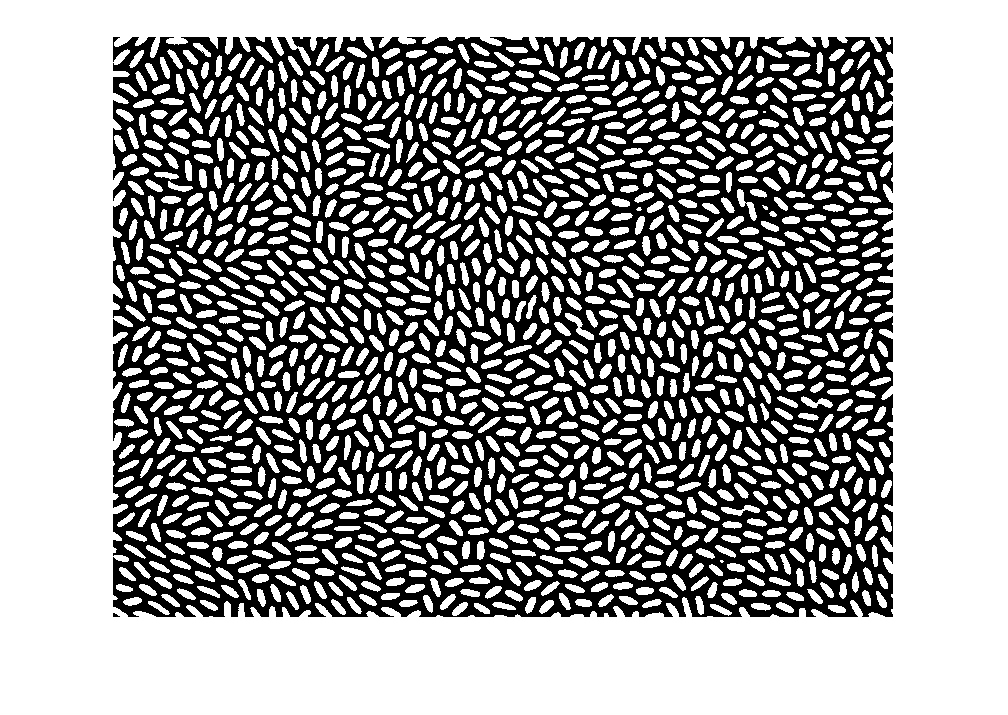

imshow(img3)

help gaussianbpf


gaussianbpf not found.

Use the Help browser search field to search the documentation, or
type "help help" for help command options, such as help for methods.



img1

img1 = 580×780 uint8 matrix
    89    71    71    84   104   135   166   190   204   219   223   233   231   243   243   243   243   223   184   134    97    78    79    92   126   162   199   227   239   243   243   243   237   226   214   179   143   111    82    80    89   120   164   204   237   243   220   173   119    79
    92    88   101   125   157   187   205   220   228   227   225   231   232   243   243   236   224   191   149   107    86    80    92   117   158   191   217   233   234   242   235   230   221   210   180   147   112    85    74    79   103   136   187   221   235   238   215   171   120    80
    94   107   136   167   199   221   231   229   234   223   220   224   230   234   229   220   197   160   123    93    85    91   112   139   180   214   225   228   234   240   234   223   202   183   155   123    87    69    71    88   121   164   204   229   241   230   205   167   123    90
    98   127   165   204   234   243   241   237   227   221   220   

filt=filter2(fspecial("average",3),img1)

filt =    37.7778   56.8889   60.0000   71.3333   88.0000  106.0000  122.5556  134.7778  143.1111  147.3333  150.8889  152.7778  157.0000  159.4444  161.2222  159.1111  151.1111  134.8889  109.7778   84.1111   64.6667   56.8889   59.7778   73.7778   94.0000  117.0000  136.5556  149.8889  157.5556  159.5556  159.5556  156.5556  151.8889  143.1111  128.4444  108.3333   86.3333   67.4444   56.7778   56.3333   67.4444   88.7778  114.6667  138.6667  153.1111  154.2222  140.0000  113.1111   82.4444   58.0000
   60.1111   94.3333  105.5556  127.1111  153.2222  178.3333  198.2222  211.8889  219.3333  222.5556  225.0000  227.6667  233.4444  236.4444  237.1111  230.8889  215.2222  188.2222  151.5556  117.5556   94.5556   88.8889   97.7778  121.6667  153.2222  185.7778  210.6667  226.2222  235.5556  238.2222  237.0000  229.7778  219.4444  203.1111  179.6667  148.8889  117.3333   92.6667   82.1111   87.4444  108.8889  143.1111  181.0000  213.5556  230.8889  229.3333  206.8889  168.1111  124.6667  

imshow(filt)